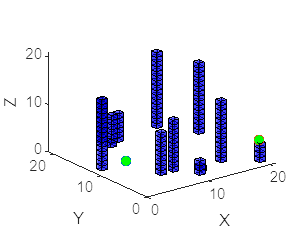

clear all
% Definizione delle dimensioni della griglia
gridSizeX = 20; % Numero di cubetti nella direzione X
gridSizeY = 20; % Numero di cubetti nella direzione Y
gridSizeZ = 20; % Numero di cubetti nella direzione Z

% Creazione della griglia 3D di cubetti
grid = zeros(gridSizeX, gridSizeY, gridSizeZ);


% Visualizzazione della griglia 3D
figure;
hold on;

n=0;

for i = 1:gridSizeX
    for j = 1:gridSizeY
        for k = 1:gridSizeZ
            if (i==10 & j==2 & k<=3) | (i==11 & j==3 & k<=1) | ...
                    (i==19 & j==1 & k<=4) | (i==15 & j==4 & k<=13) | ...
                    (i==8 & j==5 & k<=11) | (i==6 & j==5 & k<=9) | ...
                    (i==1 & j==11 & k<=15) | (i==7 & j==19 & k<=9) | ...
                    (i==7 & j==17 & k<=1) | (i==8 & j==18 & k<=6) | ...
                    (i==9 & j==18 & k<=6) | (i==9 & j==18 & k<=5) |...
                    (i==16 & j==19 & k<=16) | (i==19 & j==14 & k<=15)
                color = 'b'; % Palazzo
                grid(i,j,k) = 1;
                n=n+1;
                drawCube(i-0.5, j-0.5, k-0.5, color);
            else
                color = 'none'; % Spazio vuoto trasparente
                grid(i,j,k) = 0;
            end


        end
    end
end
hold on 
plot3(5,11,1,'o','MarkerFaceColor','g')
hold on
plot3(19,1,5,'o','MarkerFaceColor','g')

% Etichettatura degli assi
xlabel('X');
ylabel('Y');
zlabel('Z');

% Impostazione delle proporzioni degli assi
xlim([0,21]);
ylim([0,21]);
zlim([0,21]);
hold on
%plotTransforms([1,1,3], eul2quat([0,0,0]), "MeshFilePath", "cad.stl");
view(3);

function drawCube(x, y, z, color)
    vertices = [
        x, y, z;
        x+1, y, z;
        x+1, y+1, z;
        x, y+1, z;
        x, y, z+1;
        x+1, y, z+1;
        x+1, y+1, z+1;
        x, y+1, z+1
    ];
    
    faces = [
        1, 2, 3, 4;
        1, 2, 6, 5;
        2, 3, 7, 6;
        3, 4, 8, 7;
        4, 1, 5, 8;
        5, 6, 7, 8
    ];
    
    patch('Faces', faces, 'Vertices', vertices, 'FaceColor', color, 'EdgeColor', 'k', 'FaceAlpha', 0.5);
end